# Comparing Ice Thickness in the past decade

The [Climate Data Store](https://cds.climate.copernicus.eu/) is a wealth of information about the Earth's past, present and future climate.  It is freely available and functions as a one-stop shop to explore climate data. There are hundreds of data sets associated with climate change.

[The sea ice thickness dataset](https://cds.climate.copernicus.eu/cdsapp#!/dataset/satellite-sea-ice-thickness) provides monthly gridded data of sea ice thickness for the Arctic region based on satellite radar altimetry observations. Sea ice is an important component of our climate system and a sensitive indicator of climate change. Its presence or its retreat has a strong impact on air-sea interactions, the Earth’s energy budget as well as marine ecosystems. It is recognized by the Global Climate Observing System as an Essential Climate Variable. Sea ice thickness is one of the parameters commonly used to characterize sea ice, alongside sea ice concentration, sea ice edge, and sea ice type, also available in the Climate Data Store.

## Download and Extract the ice thickness data from Climate Data Store

Select the sea ice thickness dataset

datasetName = "satellite-sea-ice-thickness";

Select the data to download from the dataset (see [this webpage](https://cds.climate.copernicus.eu/cdsapp#!/dataset/satellite-sea-ice-thickness?tab=form) for options).  This is a "MATLABized" version of the python structure that is generated in the API request.

options.version = "1_0";
options.variable = "all";
options.satellite = "cryosat_2";
options.cdr_type = ["cdr","icdr"];
options.year = ["2011","2021"];
options.month = ["03"];

Download the data from Climate Data Store using `climateDataStoreDownload`.  It is put in a directory called "satellite-sea-ice-thickness."

[downloadedFilePaths,citation] = climateDataStoreDownload(datasetName,options);

2021-12-03 14:48:06,019 INFO Welcome to the CDS
2021-12-03 14:48:06,021 INFO Sending request to https://cds.climate.copernicus.eu/api/v2/resources/satellite-sea-ice-thickness
2021-12-03 14:48:06,158 INFO Request is completed
2021-12-03 14:48:06,160 INFO Downloading https://download-0012.copernicus-climate.eu/cache-compute-0012/cache/data0/dataset-satellite-sea-ice-thickness-2e9e98de-6daf-4e4e-b54c-6e2d3717bda2.zip to C:\Users\rpurser\AppData\Local\Temp\tp4fe4d917_23d3_4690_916c_a4196cc2efe0.zip (4.4M)
2021-12-03 14:48:08,901 INFO Download rate 1.6M/s


The function also returns the appropriate citation for the data

disp(citation)

Generated using Copernicus Climate Change Service information 2021


## Explore the ice thickness data

Look at one of the files (March 2021) to get variable information

filename = "satellite-sea-ice-thickness\ice_thickness_nh_ease2-250_icdr-v1p0_202103.nc";
info = ncinfo("satellite-sea-ice-thickness\ice_thickness_nh_ease2-250_icdr-v1p0_202103.nc");
info.Variables

ans = 1×11 struct array with fields:
    Name
    Dimensions
    Size
    Datatype
    Attributes
    ChunkSize
    FillValue
    DeflateLevel
    Shuffle


## Read and format ice thickness data from 2011 and 2021

Transform and load the latitude, longitude, and ice thickness.  

ice2011 = readSatelliteSeaIceThickness("satellite-sea-ice-thickness\ice_thickness_nh_ease2-250_cdr-v1p0_201103.nc");
ice2021 = readSatelliteSeaIceThickness("satellite-sea-ice-thickness\ice_thickness_nh_ease2-250_icdr-v1p0_202103.nc");
head(ice2021)

ans = 8×3 timetable
       time         lat       lon      thickness
    ___________    ______    ______    _________

    01-Mar-2021    47.629    144.03       2.4566
    01-Mar-2021    47.966     144.1         2.58
    01-Mar-2021    50.507    148.01    -0.036378
    01-Mar-2021    50.836    148.12       1.0242
    01-Mar-2021    50.324       147     0.051788
    01-Mar-2021    51.164    148.23      0.24446
    01-Mar-2021    50.911    147.66      0.89334
    01-Mar-2021    50.654    147.09      0.12714


## Visually compare March ice thickness in 2011 and 2021

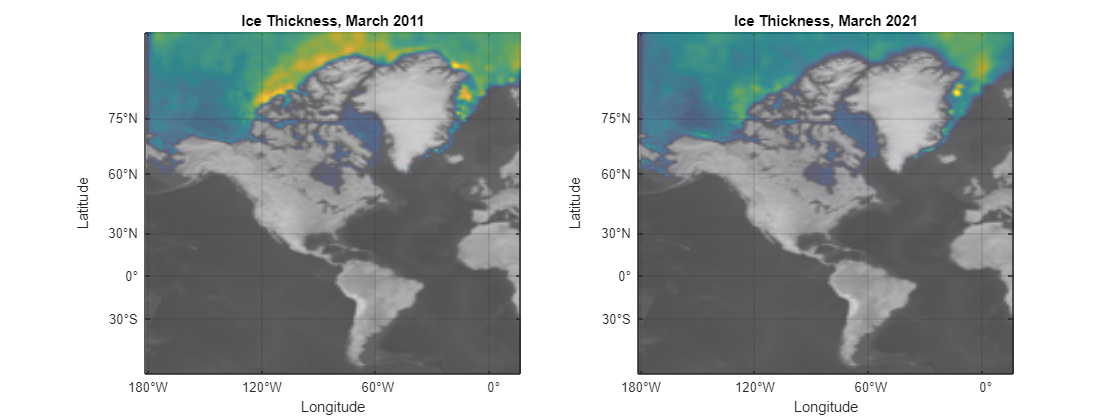

subplot(1,2,1)
geodensityplot(ice2011.lat,ice2011.lon,ice2011.thickness,"FaceColor","interp")
geolimits([23 85],[-181.4 16.4])
geobasemap("grayterrain")
title("Ice Thickness, March 2011")

subplot(1,2,2)
geodensityplot(ice2021.lat,ice2021.lon,ice2021.thickness,"FaceColor","interp")
geolimits([23 85],[-181.4 16.4])
geobasemap("grayterrain")
title("Ice Thickness, March 2021")
f = gcf;
f.Position(3) = f.Position(3)*2;

disp(citation)

Generated using Copernicus Climate Change Service information 2021


Copyright 2021-2022 The MathWorks, Inc.